## Prueba de euler

Aquí probarán las funciones relacionadas con los ángulos de euler y matrices de rotación.

## 1. Escribe la matriz de rotación *R* con los siguientes valores:

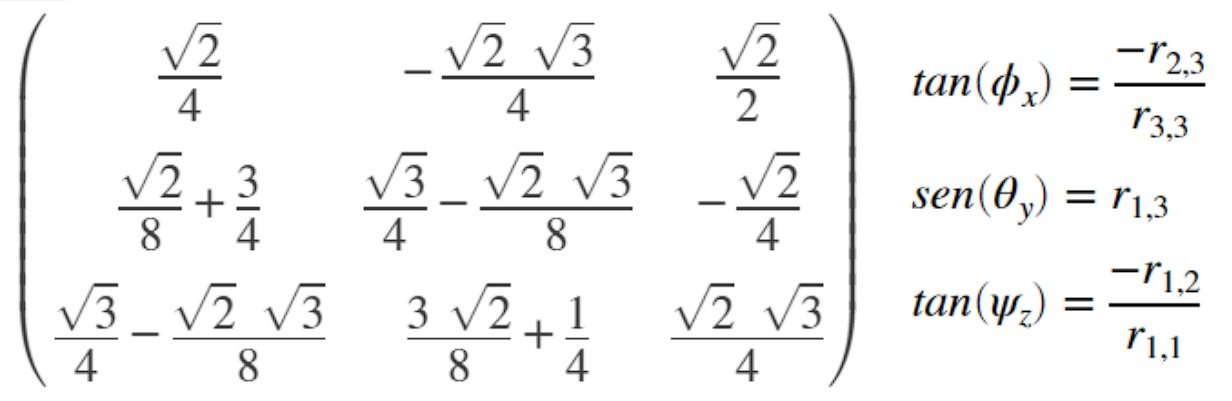

R = [sqrt(2)/4 -((sqrt(2)*sqrt(3))/4) sqrt(2)/2
     (sqrt(2)/8 + 3/4) (sqrt(3)/4 -((sqrt(2)*sqrt(3))/8)) -sqrt(2)/4
     (sqrt(3)/4 -((sqrt(2)*sqrt(3))/8)) ((3*sqrt(2))/8 + 1/4) ((sqrt(2)*sqrt(3))/4)]

R =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
    0.1268    0.7803    0.6124



% Una raiz cuadrada se escribe como sqrt(n)
% Puedes definir la matriz de rotación usando saltos de linea
% R = [1 1 1
%      1 1 1
%      1 1 1];
% O usando comas (,) y punto y coma (;).
% Usar tres puntos significa que es la misma linea, pero continúa abajo
% R = [1,1,1;...
%      1,1,1;...
%      1,1,1];
% Considero más fácil la primera opción, pero en otros lenguajes es más común la segunda.

## 2. Comprueba que es una matriz de rotación válida en base a cada uno de los vectores verticales de la matriz comprobando que la norma de cada vector es 1.


$$R=\left\lbrack \begin{array}{ccc}
\left\lbrack \begin{array}{c}
X_x \\
X_y \\
X_z 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
Y_x \\
Y_y \\
Y_z 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
Z\\
Z_y \\
Z_z 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


X = R(:,1)    % Todas las filas, primera columna

X =     0.3536
    0.9268
    0.1268


Y = R(:,2)    % Todas las filas, segunda columna

Y =    -0.6124
    0.1268
    0.7803


Z = R(:,3)    % Todas las filas, tercera columna

Z =     0.7071
   -0.3536
    0.6124



$$\begin{array}{l}
\textrm{si}:\;a=\left\lbrack \begin{array}{c}
a_x \\
a_y \\
a_z 
\end{array}\right\rbrack \\
\textrm{norm}\left(a\right)=\sqrt{{a_x }^2 +{a_y }^2 +{a_z }^2 }
\end{array}$$


norma_X = norm(X)

norma_X = 1

norma_Y = norm(Y)

norma_Y = 1

norma_Z = norm(Z)

norma_Z = 1

## 3. Modifica la función rotMat2euler para obtener los valores en ángulos de euler XYZ. 

Puedes dar click derecho en la función y darle a open "rotMat2euler".

**Cambia de ubicación las funciones que actualmente tienes, porque algunas están en la carpeta **`\quaternion`**.**

Puedes usar una estructura parecida a la de este repositorio.

euler = rotMat2euler(R,"XYZ");

phi = 0.5236

theta = 0.7854

psi = 1.0472

euler =     0.5236
    0.7854
    1.0472


%euler = rad2deg(euler);
phi = euler(1)      % phi:   rotación alrededor del eje X

phi = 0.5236

theta = euler(2)    % theta: rotación alrededor del eje Y

theta = 0.7854

psi = euler(3)      % psi:   rotación alrededor del eje Z

psi = 1.0472

## 4. Obten la matriz de rotación por rotaciones sucesivas XYZ y comprueba que coincide con la matriz inicial.


$$R_{\textrm{xyz}} =R_x R_y R_z$$


% Si quisieras formar el vector euler a partir de cada variable de rotación, puedes usar
% euler = [phi;theta;psi];

% Abre la función y edítala
Rxyz = euler2rotMat(euler,"XYZ")

phi = 0.5236

theta = 0.7854

psi = 1.0472

R =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


R =     0.7071         0    0.7071
         0    1.0000         0
   -0.7071         0    0.7071


R =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


R =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
    0.1268    0.7803    0.6124


Rxyz =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
    0.1268    0.7803    0.6124



% Si el resultado de lo siguiente es una matriz 3x3 con valores lógicos 1,
% completaste correctamente la tarea.
R

R =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
    0.1268    0.7803    0.6124


Rxyz

Rxyz =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
    0.1268    0.7803    0.6124


R == Rxyz

ans = 3×3 logical array
   0   0   1
   0   1   0
   0   0   0


result = compare_matrices(R,Rxyz, 1e-6)

result = logical
   1
